# Code used in HALO interpolation project

% Interpolation of HALO dropsondes

close all;
clear all;

## 0A. Select the HALO flight we wish to look at

DROP_ncdir = "dropsondes/";
DROP_ncfile = DROP_ncdir + "EUREC4A_HALO_dropsondes_20200207_v0.9.nc";
year = 2020; month = 2; day = 7;

datestring = "" + num2str(year) + sprintf('%02d', month) + sprintf('%02d', day);
datestring_title = "" + num2str(year) + "-" + sprintf('%02d', month) + "-" + sprintf('%02d', day);

## 0B. Load variables from HALO Dropsonde

DROP_rh = ncread(DROP_ncfile,'rh'); % relative humidity, percent
DROP_alt = ncread(DROP_ncfile,'altitude'); % altitude m of flight
DROP_height = ncread(DROP_ncfile, 'height'); % height levels of dropsonde (1D)
DROP_lat = ncread(DROP_ncfile, 'lat'); %Latitude N
DROP_lon = ncread(DROP_ncfile, 'lon'); %Longitude E
DROP_time = ncread(DROP_ncfile,'time'); % seconds since 1970-01-01 00:00:00 +0000 UTC
DROP_pres = ncread(DROP_ncfile,'p'); % pressure, hPa
DROP_launch_time = ncread(DROP_ncfile, 'launch_time'); % launch time for each dropsonde
DROP_T_a = ncread(DROP_ncfile,'ta') + 273.15; % temperature, converted to K
DROP_theta = ncread(DROP_ncfile, 'theta'); % DROP_T_a .* (1000./DROP_pres).^0.286; % potential temperature

% Convert to MATLAB datetime array (in UTC)
DROP_datetimeUTC = datetime(1970, 01, 01, 00, 00, 00) + seconds(DROP_time);
DROP_datetimeUTC_launch_time = datetime(1970, 01, 01, 00, 00, 00) + seconds(DROP_launch_time);
DROP_datetimeUTC_launch_time_of_day_hours = hours(timeofday(DROP_datetimeUTC_launch_time));

## 0C. Load variables from ERA5 Data

ERA5_ncdir = "ERA5/";
ERA5_ncfile = ERA5_ncdir + "ERA5-20200201-to-20200210.nc";

ERA5_time = ncread(ERA5_ncfile, 'time'); % hours since 1900-01-01 00:00:00.0
ERA5_T_a = ncread(ERA5_ncfile,'t'); % t(time=288, level=37, latitude=13, longitude=21);
ERA5_rh = ncread(ERA5_ncfile,'r'); % relative humidity %
ERA5_lat = ncread(ERA5_ncfile, 'latitude'); %Latitude N
ERA5_lon = ncread(ERA5_ncfile, 'longitude'); %Longitude E
ERA5_pres_level = double(ncread(ERA5_ncfile,'level'));

% create 4d array for pressure
ERA5_pres = zeros(size(ERA5_rh));
for i = 1:size(ERA5_pres_level)
    ERA5_pres(:,:,i,:) = ERA5_pres_level(i);
end

ERA5_theta = ERA5_T_a .* (1000./ERA5_pres).^0.286; % potential temperature

% Convert to MATLAB datetime array (in UTC)
ERA5_time = datetime(1900, 01, 01, 00, 00, 00) + hours(ERA5_time);

## 1A. 1D Dropsonde plot

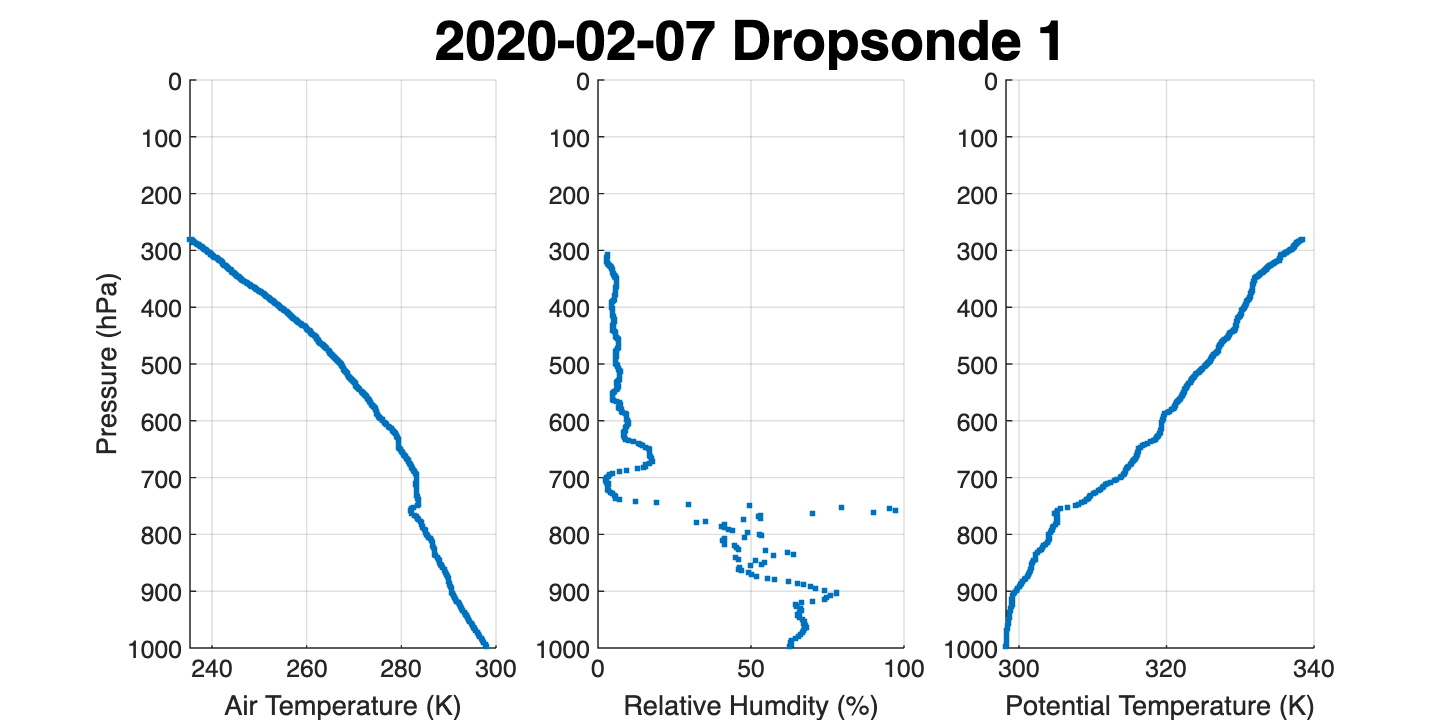

figure('position', [0,0,800,400]);

subplot(1,3,1); hold on;
scatter(DROP_T_a(:,1),DROP_pres(:,1),'.');hold on;
set(gca, 'YDir','reverse')
xlabel('Air Temperature (K)')
ylabel('Pressure (hPa)')
ylim([0 1000]);
grid on;

subplot(1,3,2);
scatter(DROP_rh(:,1),DROP_pres(:,1),'.');hold on;
set(gca, 'YDir','reverse')
xlabel('Relative Humdity (%)')
ylim([0 1000]);
grid on;
title(datestring_title+" Dropsonde 1", 'FontSize', 20);

subplot(1,3,3);
scatter(DROP_theta(:,1),DROP_pres(:,1),'.');hold on;
set(gca, 'YDir','reverse')
xlabel('Potential Temperature (K)')
ylim([0 1000]);
grid on;

hold on;
saveas(gcf, strcat(datestring_title, '_dropsondes_1D.png'))

## 1B. 2D Flight + Dropsonde location plot

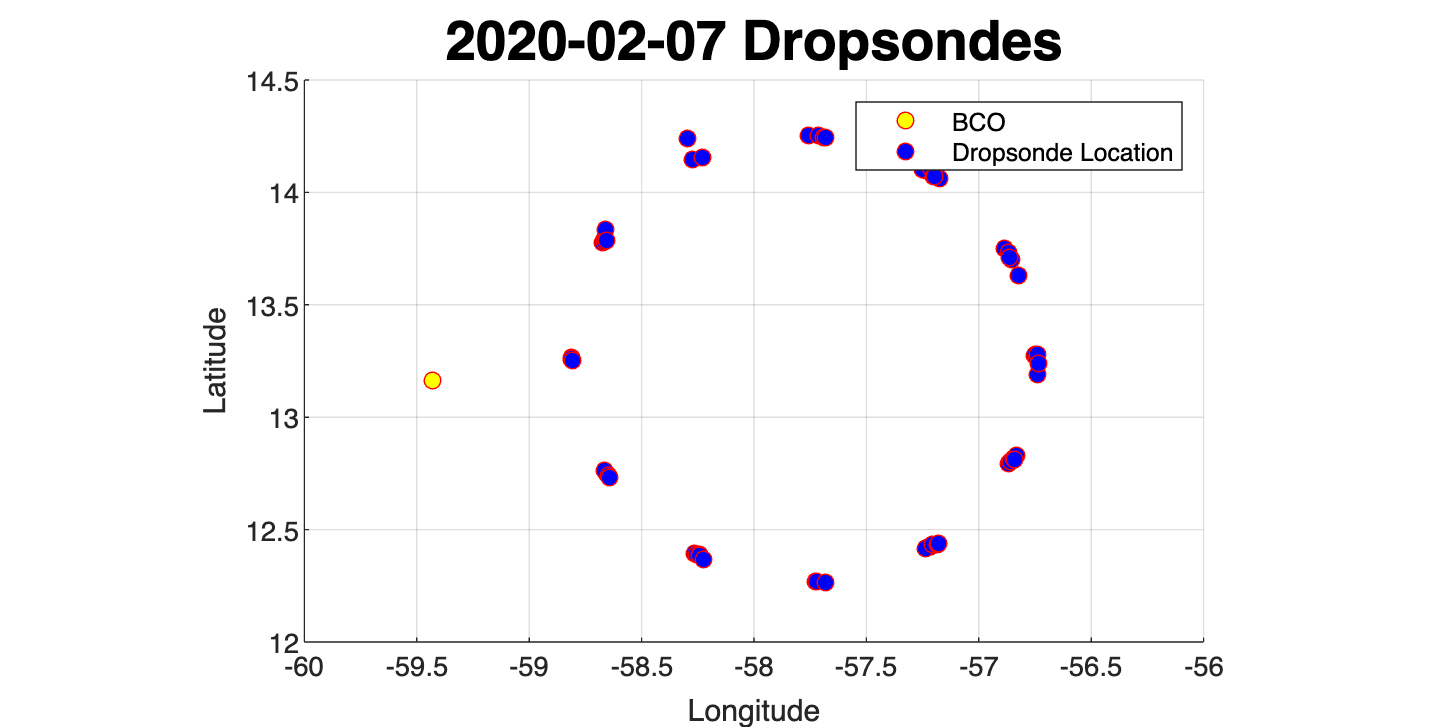

figure('position', [0,0,800,400]);
scatter([-59.42875], [13.162639], 'c', 'MarkerFaceColor', 'yellow', 'MarkerEdgeColor', 'red','DisplayName','BCO'); % BCO location 13°9′45.5″N, 59°25′43.5″W or 13.162639, -59.42875
hold on;

scatter(DROP_lon(1,:),DROP_lat(1,:), 'c', 'MarkerFaceColor', 'blue', 'MarkerEdgeColor', 'red','DisplayName','Dropsonde Location');
hold on;

axis equal;
grid on;
legend('Location','northeast');
xlim([-60, -56]);xlabel('Longitude');
ylim([12, 14.5]);ylabel('Latitude');
title(datestring_title+" Dropsondes", 'FontSize', 20);

saveas(gcf, strcat(datestring_title, '_dropsondes_map.png'))

## 1C. Plot 3D diagram of the dropsondes

% see figure plotted later.

## 2A. Demonstration of Runge's phenomenon for 1D (single) dropsonde

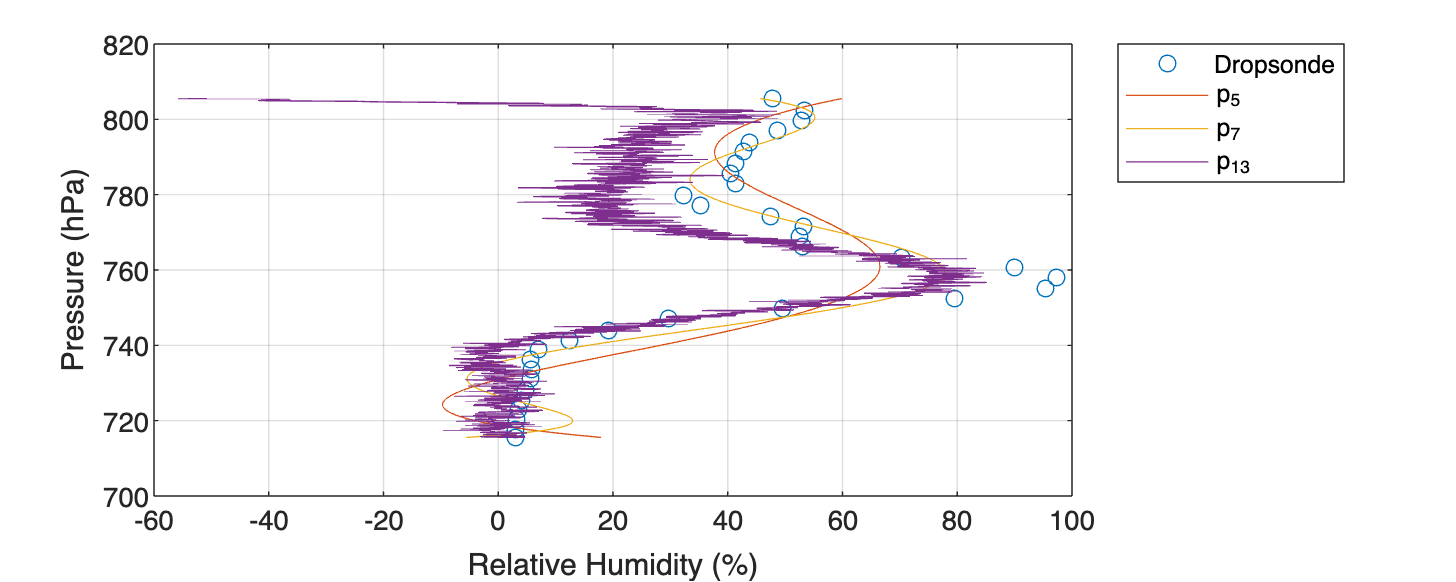

clear x; clear y;
ws = warning('off','all');

x = DROP_pres(68:101,1);
y = DROP_rh(68:101,1);
xq = linspace(x(1),x(end), 1000); % evaluate the polynomial interpolation at many points
figure('Position', [10 10 1000 400]);
plot(y,x, 'o','DisplayName','Dropsonde'); hold on;

p1 = polyfit(x,y,5);
y1 = polyval(p1, xq);
plot(y1,xq,'DisplayName','p_{5}');

p2 = polyfit(x,y,7);
y2 = polyval(p2, xq);
plot(y2,xq,'DisplayName','p_{7}');

p3 = polyfit(x,y,13);
y3 = polyval(p3, xq);
plot(y3,xq,'DisplayName','p_{13}');


%ylim([2000,3000]); xlim([0,100])
ylabel('Pressure (hPa)')
xlabel('Relative Humidity (%)');
grid on;
legend('Location','northeastoutside');

saveas(gcf, strcat(datestring_title, '_runge_1.png'))

## 2B. Demonstration of different 1d interp methods, and ERA5 comparison

Retrieve ERA5 for nearest gridpoint

[DROP_lat(1,1),DROP_lon(1,1)]

ans =    13.2556  -58.8121


DROP_datetimeUTC_launch_time(1)

ans = datetime
   07-Feb-2020 12:22:05


% indexing
env_lat_i = 6;
env_lon_i = 8;
env_time_i = 157;
ERA5_lat(env_lat_i)

ans = single
13.7500

ERA5_lon(env_lon_i)

ans = single
-58.2500

ERA5_time(157)

ans = datetime
   07-Feb-2020 12:00:00


figure('position', [0,0,1700,800]);

subplot(1,3,1);



x = DROP_pres(68:101,1);
y = DROP_T_a(68:101,1);
xq = linspace(x(1),x(end), 1000); % evaluate the polynomial interpolation at many points
plot(y,x, 'o','DisplayName','Dropsonde'); hold on;
y1 = interp1(x,y, xq, 'linear');
plot(y1,xq,'DisplayName','linear');
y2 = interp1(x,y, xq, 'cubic');

plot(y2,xq,'DisplayName','cubic');
y3 = interp1(x,y, xq, 'makima');
plot(y3,xq,'DisplayName','makima');
plot(reshape(ERA5_T_a(env_lon_i,env_lat_i,:, env_time_i),[1,37]),ERA5_pres_level,'DisplayName','ERA5');
ylim([720,800]); %xlim([0,100])
grid on;xlabel('Air Temperature (K)')
ylabel('Pressure (hPa)')
set(gca, 'YDir','reverse')
grid on;

subplot(1,3,2);
x = DROP_pres(68:101,1);
y = DROP_rh(68:101,1);
xq = linspace(x(1),x(end), 1000); % evaluate the polynomial interpolation at many points
plot(y,x, 'o','DisplayName','Dropsonde'); hold on;
y1 = interp1(x,y, xq, 'linear');
plot(y1,xq,'DisplayName','linear');
y2 = interp1(x,y, xq, 'cubic');

plot(y2,xq,'DisplayName','cubic');
y3 = interp1(x,y, xq, 'makima');
plot(y3,xq,'DisplayName','makima');
plot(reshape(ERA5_rh(env_lon_i,env_lat_i,:, env_time_i),[1,37]),ERA5_pres_level,'DisplayName','ERA5');
ylim([720,800]); %xlim([0,100])
grid on;xlabel('Air Temperature (K)')
ylabel('Pressure (hPa)')
set(gca, 'YDir','reverse')
grid on;
title(datestring_title+" Dropsonde 1", 'FontSize', 20);


subplot(1,3,3);
x = DROP_pres(68:101,1);
y = DROP_theta(68:101,1);
xq = linspace(x(1),x(end), 1000); % evaluate the polynomial interpolation at many points
plot(y,x, 'o','DisplayName','Dropsonde'); hold on;
y1 = interp1(x,y, xq, 'linear');
plot(y1,xq,'DisplayName','linear');
y2 = interp1(x,y, xq, 'cubic');

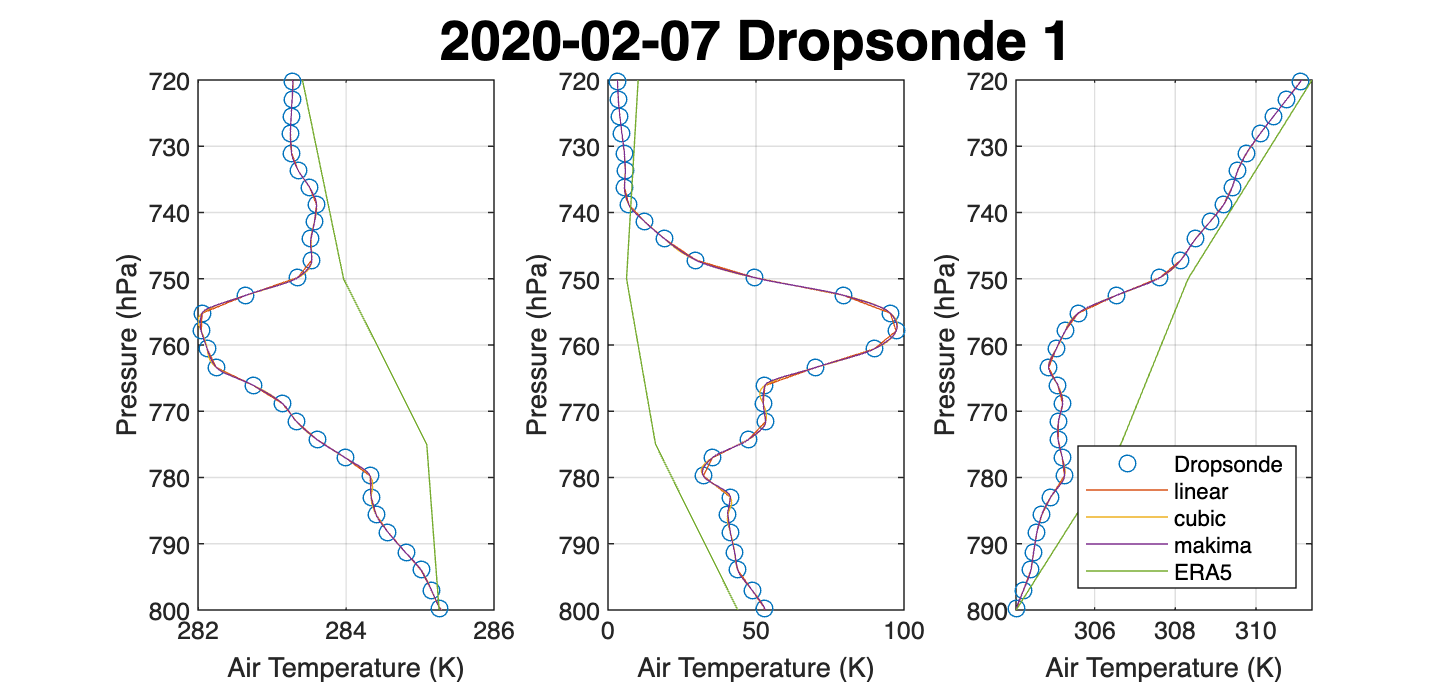

plot(y2,xq,'DisplayName','cubic');
y3 = interp1(x,y, xq, 'makima');
plot(y3,xq,'DisplayName','makima');
plot(reshape(ERA5_theta(env_lon_i,env_lat_i,:, env_time_i),[1,37]),ERA5_pres_level,'DisplayName','ERA5');
ylim([720,800]); %xlim([0,100])
grid on;xlabel('Air Temperature (K)')
ylabel('Pressure (hPa)')
set(gca, 'YDir','reverse')
grid on;


legend('Location','southeast');

saveas(gcf, strcat(datestring_title, '_dropsondes_1D_interp.png'))

## clear x; clear y;

clear x; clear y;warning(ws);

## 3. 3D Interpolation Attempt on Dropsondes

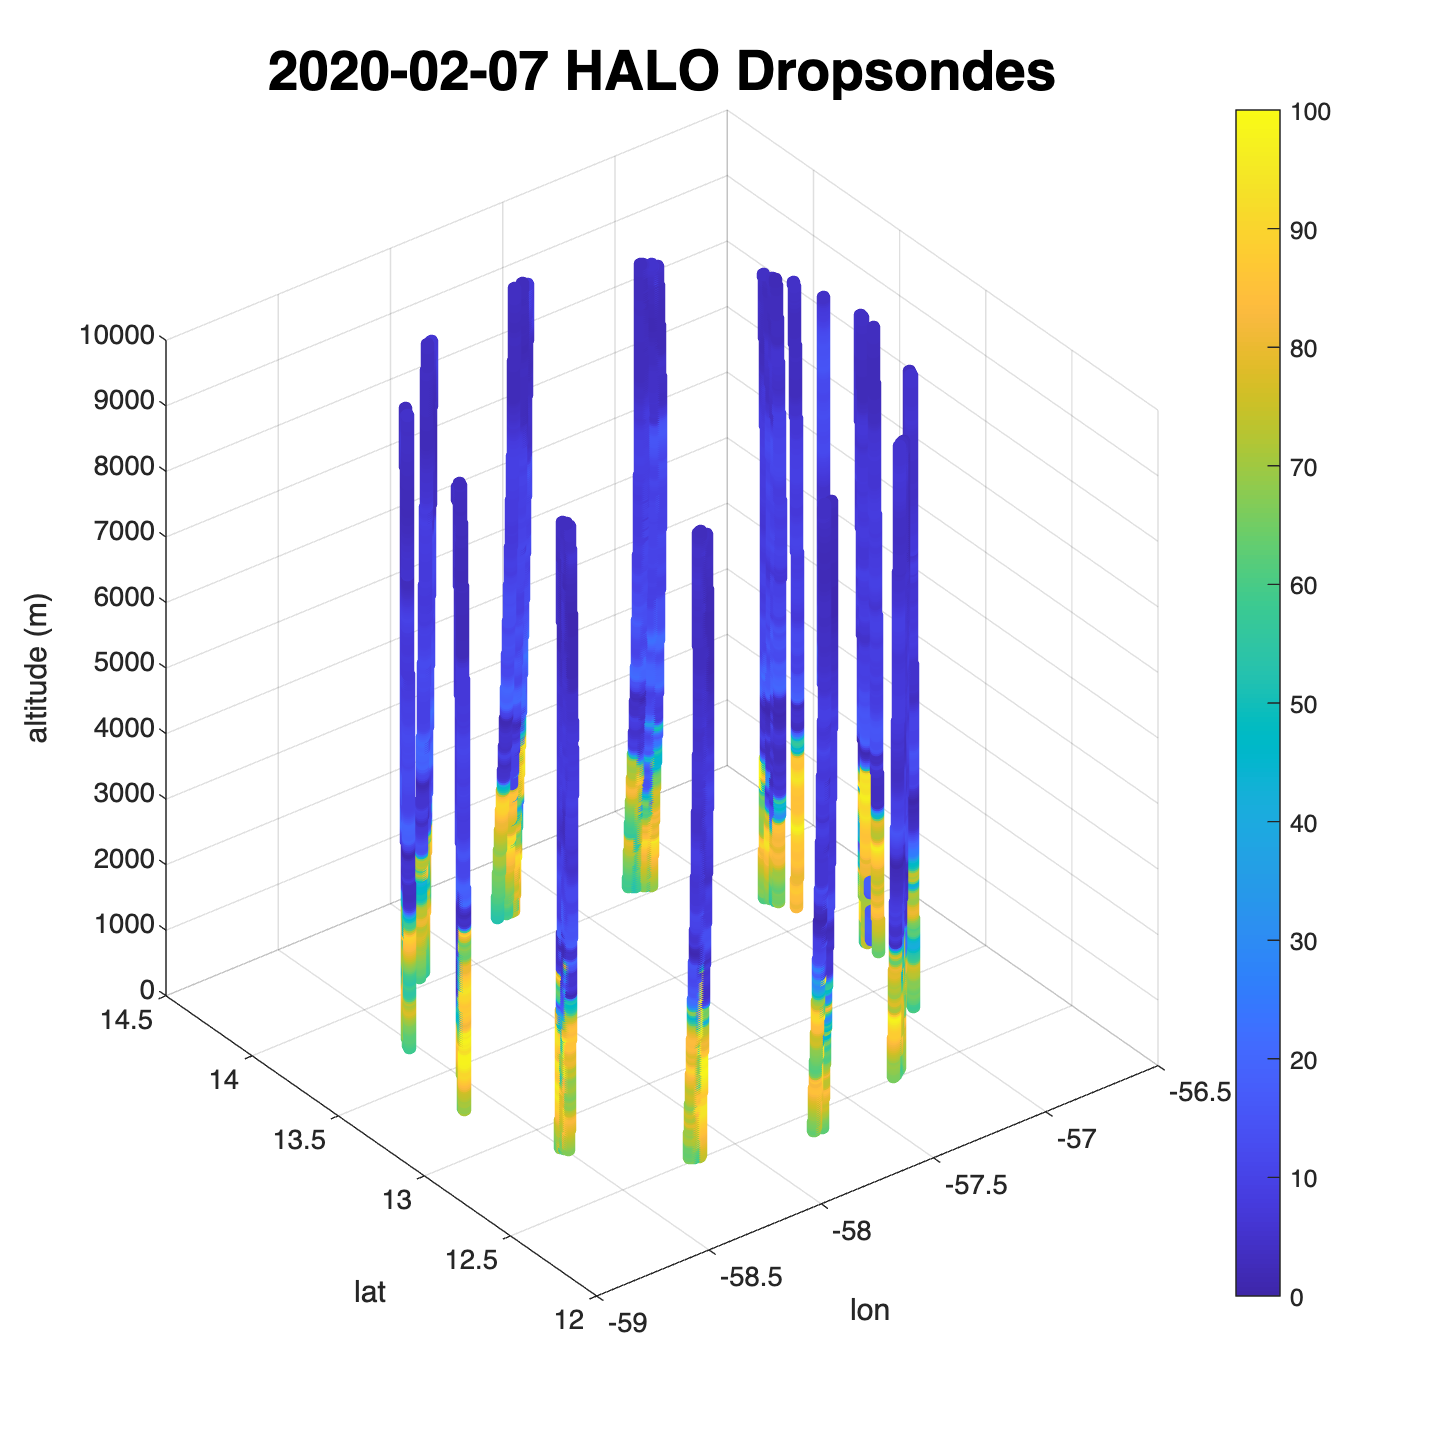

interp_data = []; % data to interpolate on...

% convert dropsonde location to theta (radians)
lon_center = -57.72;
lat_center = 13.30;
radius = 100/111;
DROP_alpha = atan2(DROP_lat - lat_center, DROP_lon - lon_center); % alpha angle from N direction, clockwise

% gather data for all dropsondes
for i = 1:73 %1:length(dropsondes_list)
    phi = DROP_rh(:,i);
    
    alpha = DROP_alpha(:,i);
    
    logicalData = ~isnan(phi) & ~isnan(alpha);
    
    alpha = alpha(logicalData);
    
    height = DROP_height(logicalData);
    
    time = DROP_datetimeUTC_launch_time_of_day_hours(i) + zeros(length(phi),1);
    
    % duplicate above/below by 2pi
    interp_data = [interp_data; phi(logicalData), alpha, height, time(logicalData); phi(logicalData), alpha+2*pi, height, time(logicalData); phi(logicalData), alpha-2*pi, height, time(logicalData)];
end

% query points
alpha_q = linspace(-3*pi, 3*pi, 150); % delta alpha of dropsondes is 0.5 rad.
h_q = linspace(min(interp_data(:,3)), max(interp_data(:,3)), 300); % delta h of dropsondes is 30m.
t_q = DROP_datetimeUTC_launch_time_of_day_hours(10);%linspace(DROP_datetimeUTC_launch_time_of_day_seconds(1), DROP_datetimeUTC_launch_time_of_day_seconds(end), 10);

[alpha_m, h_m, t_m] = meshgrid(alpha_q,h_q,t_q);

F = scatteredInterpolant(interp_data(:,2), interp_data(:,3), interp_data(:,4), interp_data(:,1));
v_q = F(alpha_m, h_m, t_m);

% plot points of dropsondes (for a given time...)
x_polar = lon_center + radius * cos(interp_data(:,2));
y_polar = lat_center + radius * sin(interp_data(:,2));

x_polar_q = lon_center + radius * cos(alpha_m);
y_polar_q = lat_center + radius * sin(alpha_m);


figure('Position', [10 10 1000 1000]);
foo = interp_data(:,3);
foo2 = interp_data(:,1);
scatter3(x_polar, y_polar, foo, [], foo2, 'filled', 'SizeData',25); hold on;
xlabel('lon');ylabel('lat');zlabel('altitude (m)')
%zlim([0,2500]);
colorbar;
lims = clim;
clim([0 100]);
title(datestring_title+" HALO Dropsondes", 'FontSize', 20);
saveas(gcf, strcat(datestring_title, '_interp_data_3D.png'))

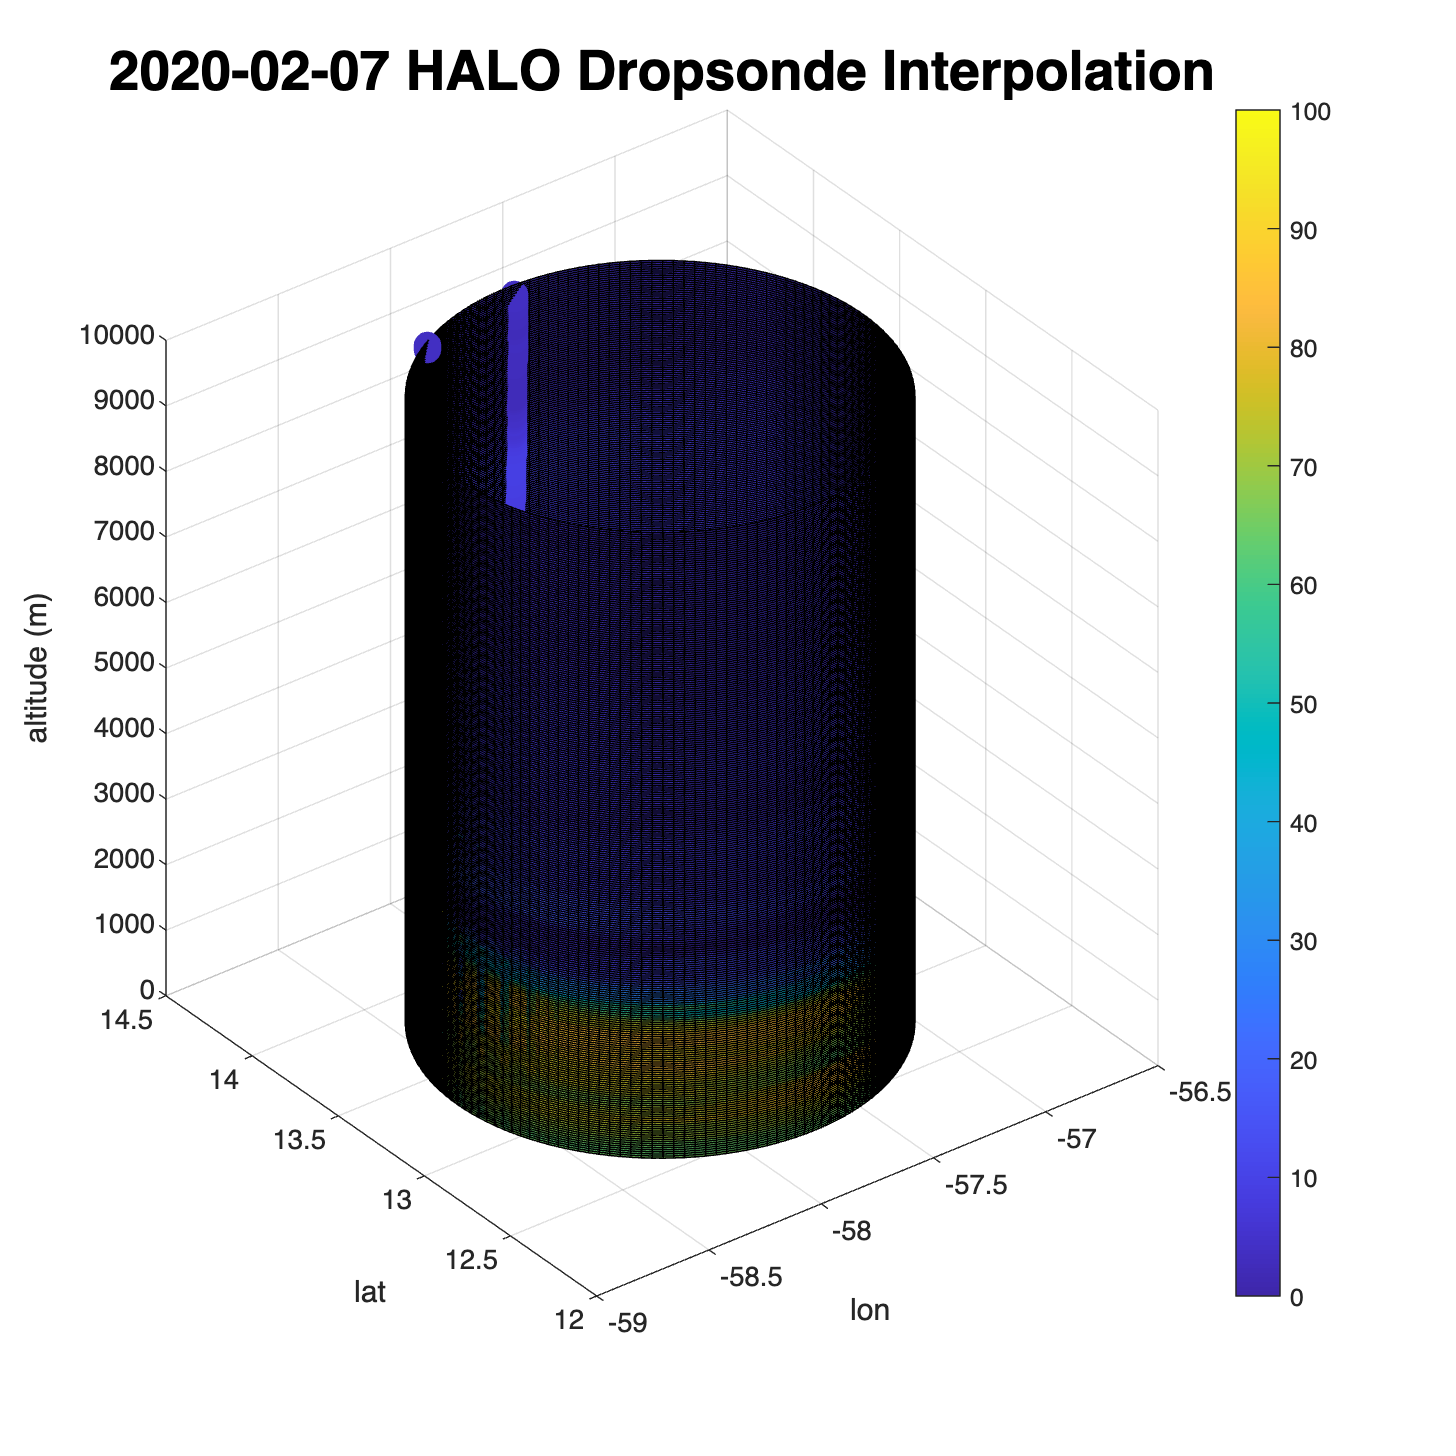


figure('Position', [10 10 1000 1000]);
foo = interp_data(:,3);
foo2 = interp_data(:,1);
dropsondefoo = 2857:3173;
scatter3(x_polar(dropsondefoo), y_polar(dropsondefoo), foo(dropsondefoo), [], foo2(dropsondefoo), 'filled', 'SizeData',100); hold on;
surf(x_polar_q, y_polar_q, h_m, v_q); hold on;
xlabel('lon');ylabel('lat');zlabel('altitude (m)')
%zlim([0,2500]);
colorbar;
lims = clim;
clim([0 100]);
title(datestring_title+" HALO Dropsonde Interpolation", 'FontSize', 20);
saveas(gcf, strcat(datestring_title, '_interp_3D.png'))

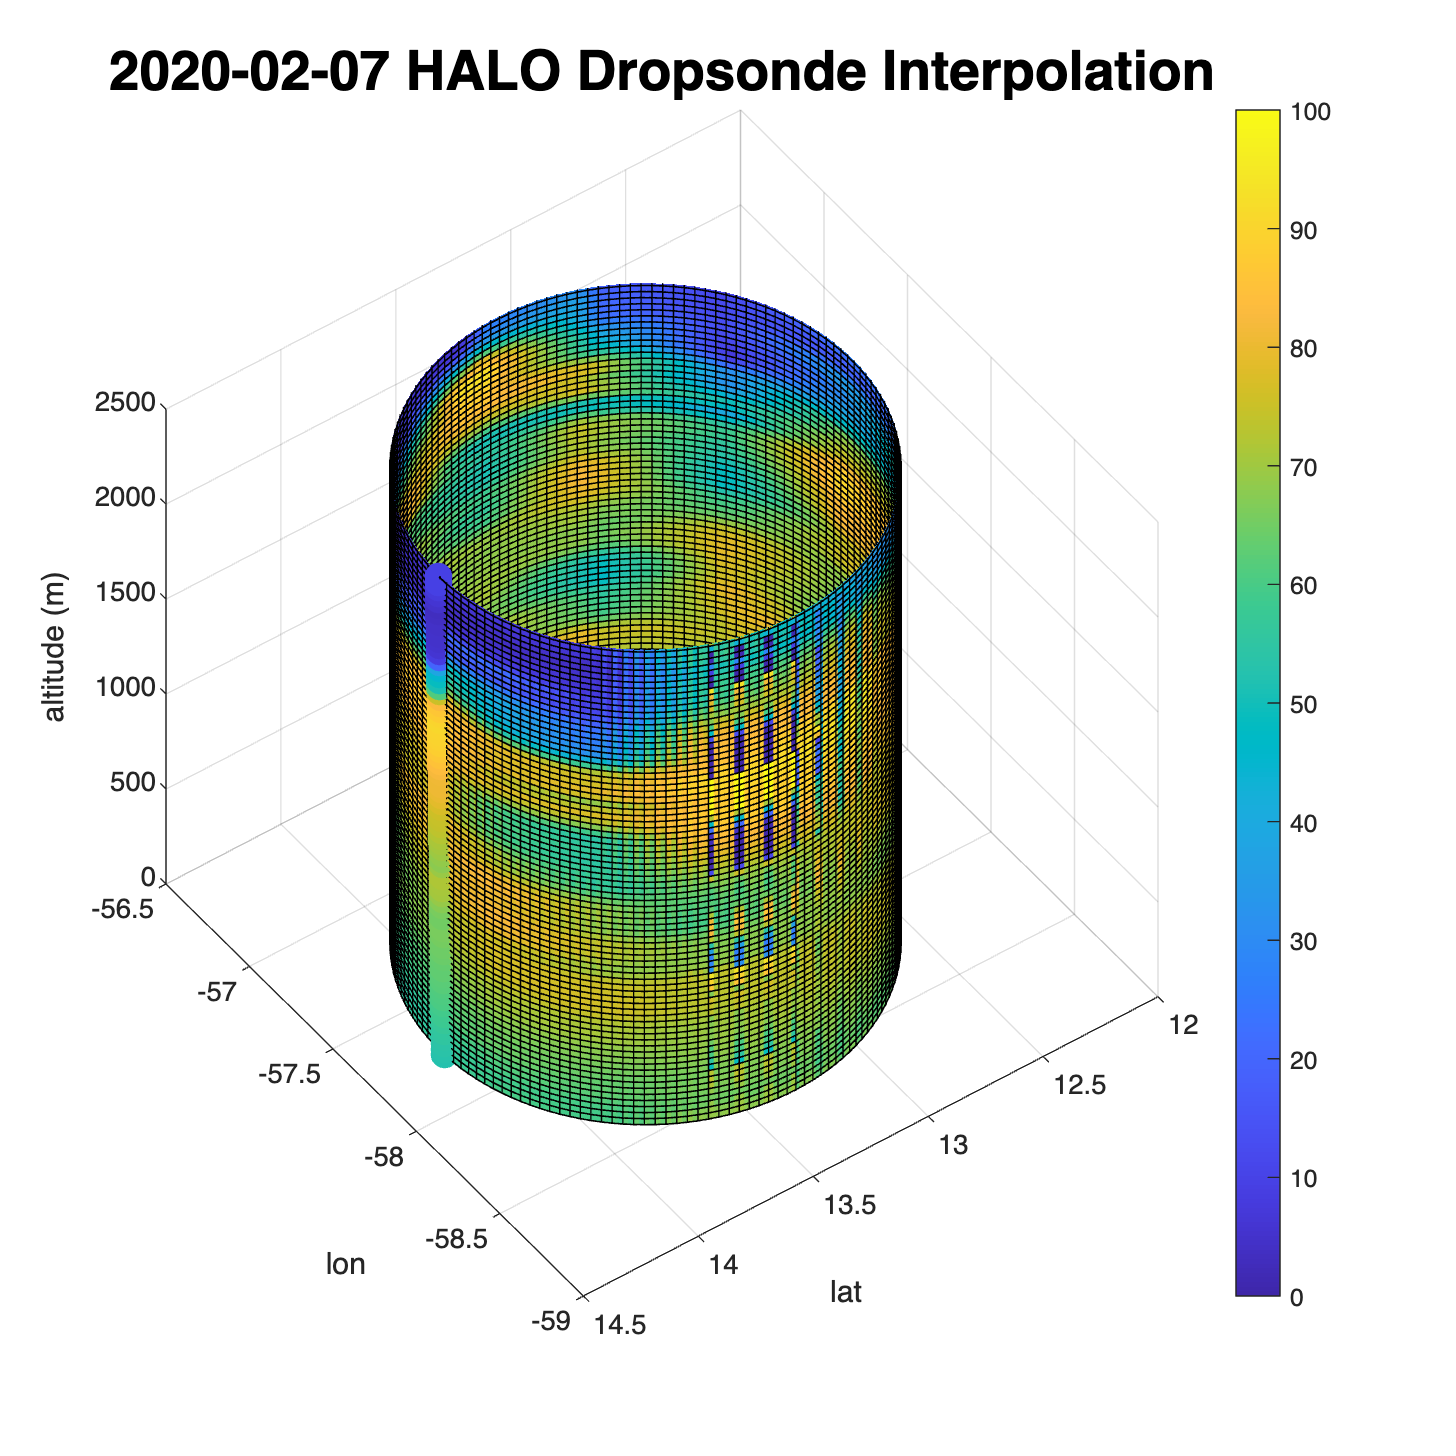



figure('Position', [10 10 1000 1000]);
foo = interp_data(:,3);
foo2 = interp_data(:,1);
dropsondefoo = 2857:3173;
scatter3(x_polar(dropsondefoo), y_polar(dropsondefoo), foo(dropsondefoo), [], foo2(dropsondefoo), 'filled', 'SizeData',100); hold on;
surf(x_polar_q, y_polar_q, h_m, v_q); hold on;
xlabel('lon');ylabel('lat');zlabel('altitude (m)')
zlim([0,2500]);
colorbar;
lims = clim;
clim([0 100]);
title(datestring_title+" HALO Dropsonde Interpolation", 'FontSize', 20);

view([-126 47])
  

saveas(gcf, strcat(datestring_title, '_interp_3D_cropped.png'))

% %vq = griddata(interp_data(:,2), interp_data(:,3), interp_data(:,4), interp_data(:,1) ,alpha_m, h_m, t_m,'linear'); %griddata(x,y,z,v,xq,yq,zq);
% 
% % average vertical profile at time
% figure('Position', [10 10 200 600]);
% plot(mean(v_q,2), h_q);
% xlabel('RH%'); ylabel('alt (m)')
% title(""+num2str(t_q(1))+' hours, profile of RH% of interpolated points, averaged wrt alpha')

## Plot 2d plot of theta vs time.

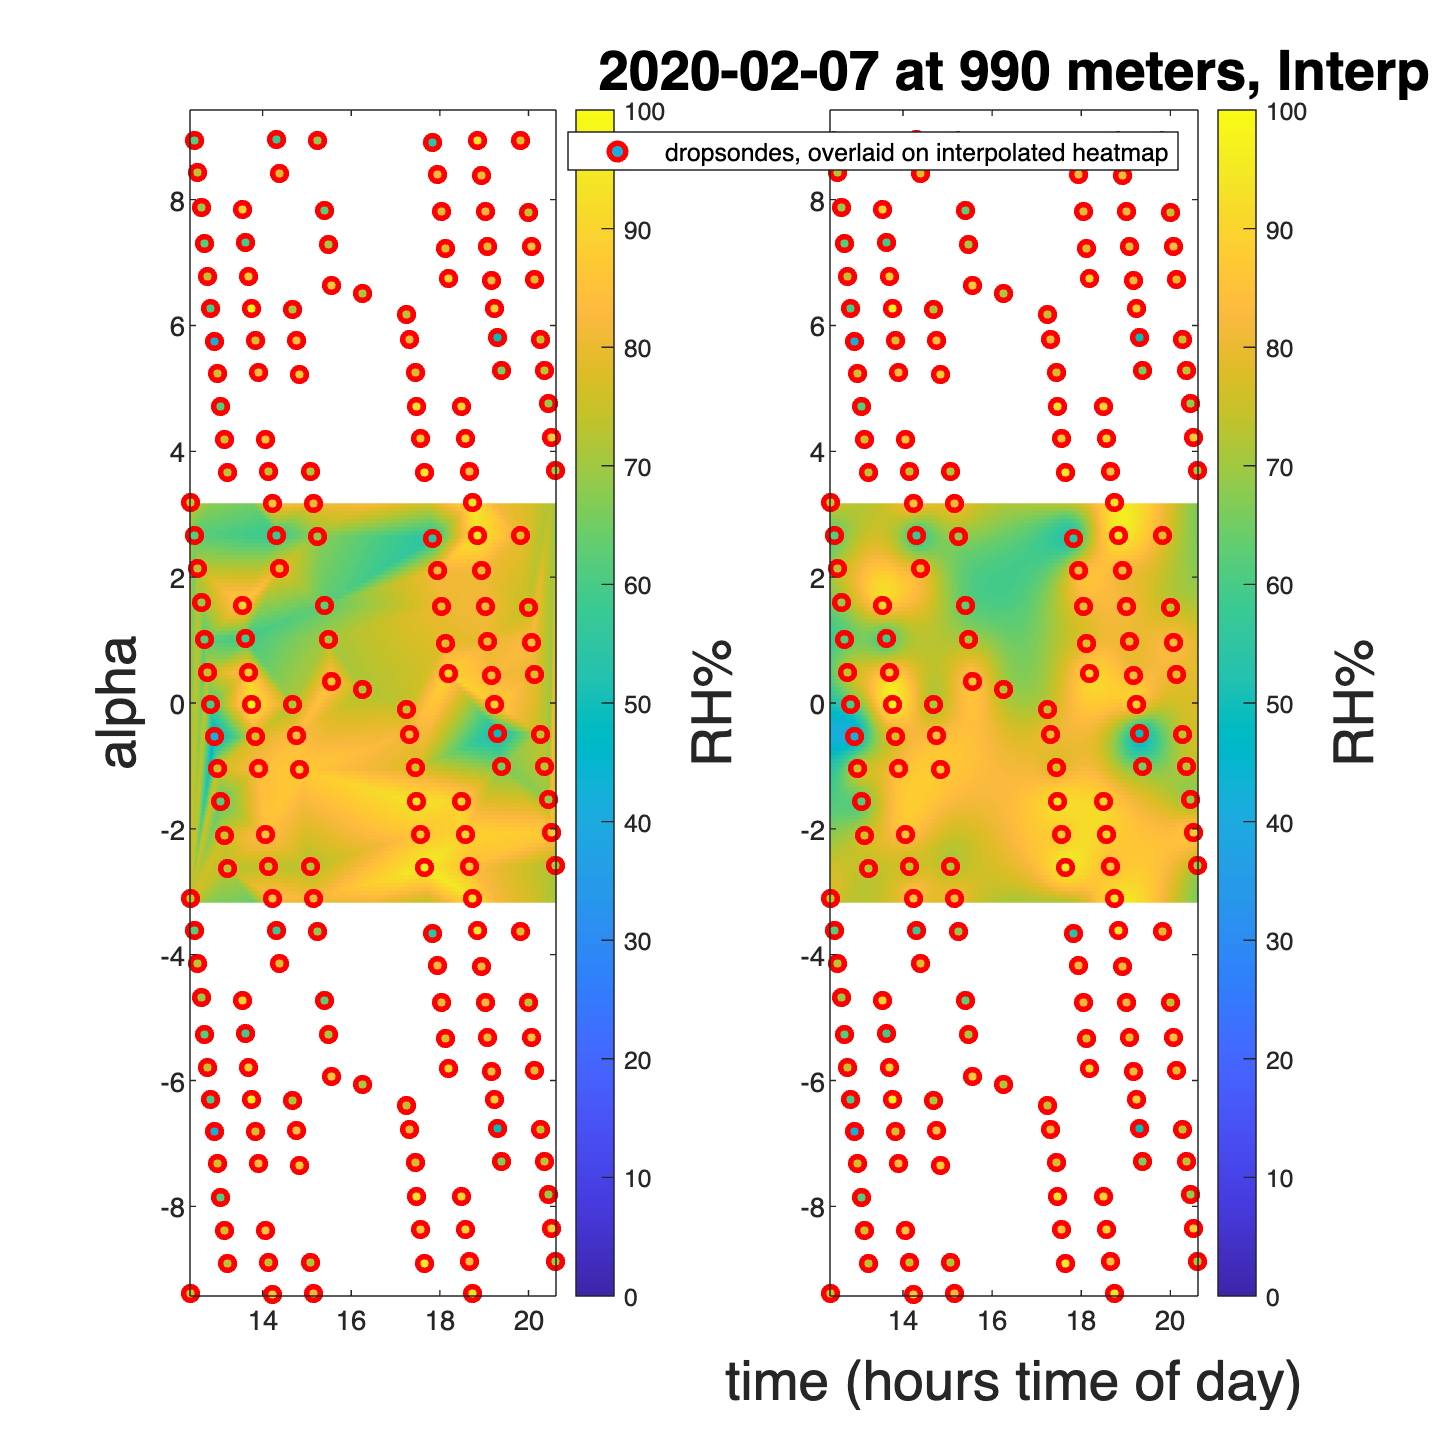

h = 990; % we want the 2d plot at h=990 m

% grab dropsonde readings at selected height
selectedRows = interp_data(interp_data(:, 3) == h, :);

% query points
alpha_q2 = linspace(-pi, pi, 100);
t_q2 = linspace(DROP_datetimeUTC_launch_time_of_day_hours(1), DROP_datetimeUTC_launch_time_of_day_hours(end), 500);
[t_m2, alpha_m2] = meshgrid(t_q2, alpha_q2);

% use griddata function in Matlab
v_q2 = griddata(selectedRows(:,4),selectedRows(:,2),selectedRows(:,1), t_m2, alpha_m2, 'linear');

% plot heatmap of interpolated data, overlaid with dropsonde points
figure('Position', [10 10 1000 1000]);

subplot(1,2,1);
imagesc([min(t_q2), max(t_q2)], [min(alpha_q2), max(alpha_q2)], v_q2, 'AlphaData',~isnan(v_q2)); hold on;
scatter(selectedRows(:,4), selectedRows(:,2), 25, selectedRows(:,1), 'filled', 'MarkerEdgeColor', 'red', 'LineWidth', 2);
a = colorbar; ylabel(a, 'RH%', 'FontSize', 20)
lims = clim;
clim([0 100]);
set(gca, 'YDir','normal');
ylabel('alpha', 'FontSize', 20)
ylim([-3*pi, 3*pi]);

subplot(1,2,2);
v_q2 = griddata(selectedRows(:,4),selectedRows(:,2),selectedRows(:,1), t_m2, alpha_m2, 'v4');
imagesc([min(t_q2), max(t_q2)], [min(alpha_q2), max(alpha_q2)], v_q2, 'AlphaData',~isnan(v_q2)); hold on;
scatter(selectedRows(:,4), selectedRows(:,2), 25, selectedRows(:,1), 'filled', 'MarkerEdgeColor', 'red', 'LineWidth', 2);
a = colorbar; ylabel(a, 'RH%', 'FontSize', 20)
lims = clim;
clim([0 100]);
set(gca, 'YDir','normal');
xlabel('time (hours time of day)', 'FontSize', 20)

title(datestring_title+" at "+num2str(h)+" meters, Interp", 'FontSize', 20);

legend('dropsondes, overlaid on interpolated heatmap')

saveas(gcf, strcat(datestring_title, '_interp2D.png'))

ylim([-3*pi, 3*pi]);
saveas(gcf, strcat(datestring_title, '_interp2D_full.png'))

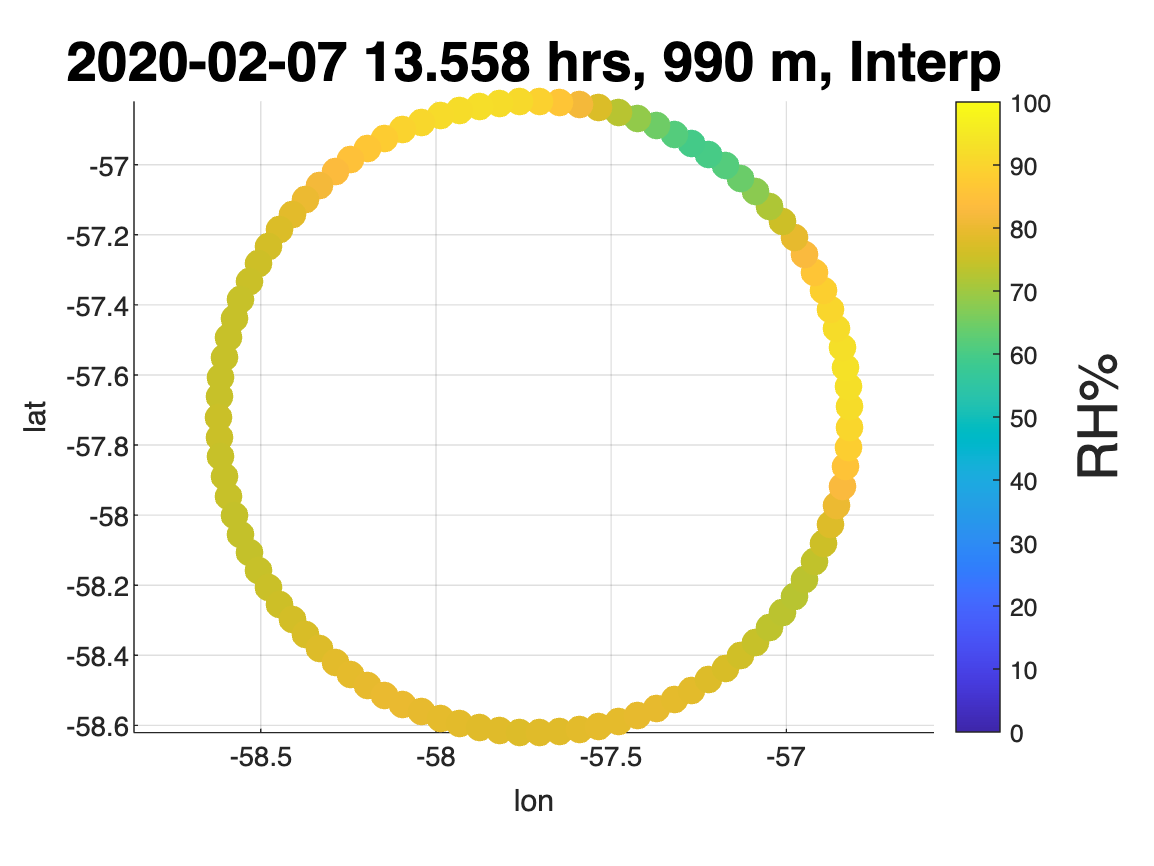



% create gif animation of dropsonde  during day
figure;
grid on; axis equal; xlabel('lon'); ylabel('lat');
a = colorbar; ylabel(a, 'RH%', 'FontSize', 20)
lims = clim;
clim([0 100]);
hold on;

    scatter(lon_center + radius * cos(alpha_m2(:,2)), lon_center + radius * sin(alpha_m2(:,2)), 100, v_q2(:,i), 'filled');
    title(datestring_title+" "+sprintf('%06.3f', t_q2(i))+" hrs, "+num2str(h)+" m, Interp", 'FontSize', 20);
    
    saveas(gcf, strcat(datestring_title, '_interp2D_horiz.png'))